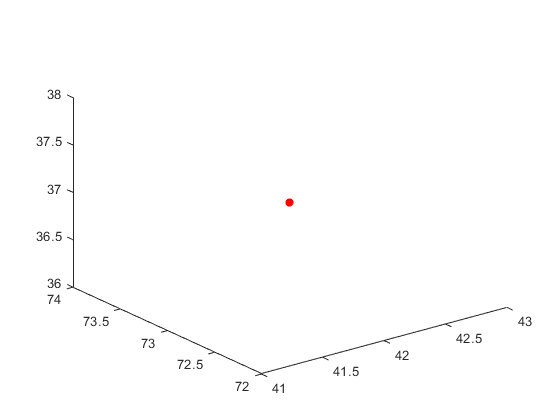

ans =     30    69     0
    28    66     0
     0   100     0
     0   100     0
    28    66     0
    26    62     0
    26    62     0
    24    58     0
     0   100     0
     0   100     0


% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\cubeWithHole.STL");

% Rotated stl
rotatedSTL = stlRotate(stl1);
rotatedSGO = FlatUniformSliceGenerator(rotatedSTL,10);
rotatedSGO.generateSlices();

op2 = rotatedSGO.getSlicePath();

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 20)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [184×3 double]
       numOfElements: 184
              points: [92×3 int64]
      sliceThickness: 20
           slicePath: [0×3 double]


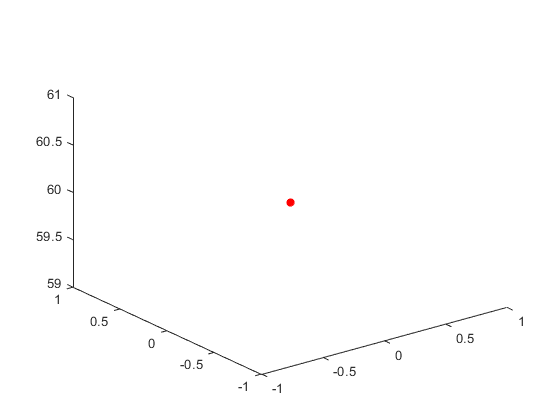

ans =      0    37     0
     0    37     0
     0    37     0
     0    37     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [750×3 double]
       numOfElements: 750
              points: [371×3 int64]
      sliceThickness: 20
           slicePath: [488×3 double]



% Generate
figure(3)
uSGO1.generateSlices()

op = uSGO1.getSlicePath()

op =      0    37     0
     0    37     0
     0    37     0
     0    37     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


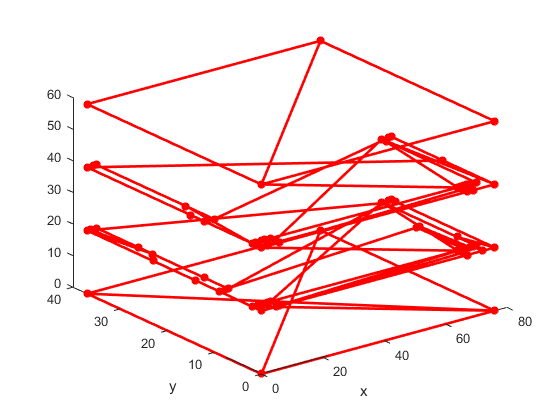


% Show
figure(4)
plot3(op(:,1), op(:,2), op(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
view(3);
hold on

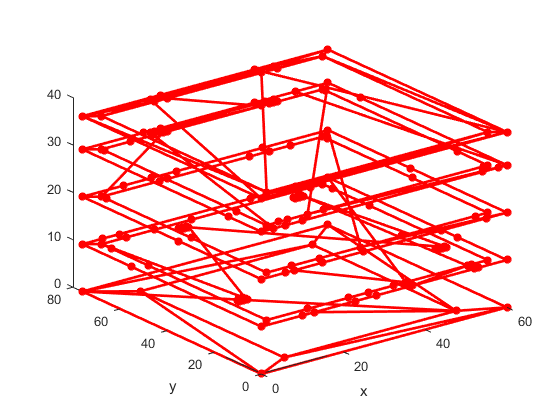


% Show 2
figure(7)
plot3(op2(:,1), op2(:,2), op2(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
view(3);
hold on


% %edge detection test
% %find unique
% [C,ia,~] = unique(op2(:,3));
% for i=1:height(ia)-1
%     x=op2(ia(i):ia(i+1)-1,1);
%     y=op2(ia(i):ia(i+1)-1,2);
%     k=boundary(x,y);
%     z = zeros(height(x(k)),1);
%     z(:)=C(i);
%     figure(5);
%     hold on
%     plot3(x(k),y(k),z)
%     slicePath = [x(k),y(k),z];
%     
%     %do last part
%     if i==height(ia)-1
%         x=op2(ia(end):height(op2),1);
%         y=op2(ia(end):height(op2),2);
%         k=boundary(x,y);
%         z = zeros(height(x(k)),1);
%         z(:)=C(end);
%         figure(5);
%         hold on
%         plot3(x(k),y(k),z)
%         slicePath = [x(k),y(k),z];
%         
%         view(3);
%     end
% end

